# Running Python Code With MATLAB

There are many programming languages in the world and they all have different features. You may have occasions where you want to reuse existing code, call on functionality from another language, or collaborate with someone who prefers to work in a different language than you. It is quite possible to use multiple programming languages together, although in some cases the interface may be awkward if the underlying structures are different. This script introduces a Live Task that can be used as a graphical user interface to run Python code from MATLAB.

This script is intended to be run one section at a time, in order. If you choose to skip around, you may encounter errors.

## Getting ready

### Step 1: Check your MATLAB version 

Including user-authored Live Tasks is only supported starting in R2022a. What version are you running?

releaseInfo = matlabRelease;
str = "This is release " + releaseInfo.Release + ",";
if isMATLABReleaseOlderThan("R2022a")
    disp(str + " so it will not run this example.")
else
    disp(str + " so you can proceed with this script.")
end

This is release R2023b, so you can proceed with this script.


### Step 2: Check your Python version

You must have Python installed, and it must be a [supported version of Python](https://www.mathworks.com/content/dam/mathworks/mathworks-dot-com/support/sysreq/files/python-compatibility.pdf) for your MATLAB version. For R2022a, you need to use 2.7, 3.8, or 3.9. What version are you using?

localCheckPythonVersion;

You are running Python 3.11
That is not compatible with this script.
Please follow the instructions in the documentation to proceed with this script.


If you do not have a supported version of Python installed, follow the instructions in the [documentation to install and select](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html) a supported version. If you have a supported version of Python installed, but it is not on your MATLAB path, you will need to add it using `addpath`

### Step 3: Download and install the MATLAB Live Task for Python

Clone the GitHub repository containing [MATLAB-Live-Task-for-Python](https://github.com/mathworks/MATLAB-Live-Task-for-Python.git). 

You can find the **Home** tab of the toolstrip and select **New**. In that dropdown menu, select **Project** and then **From Git**. Type or paste the address  [`https://github.com/mathworks/MATLAB-Live-Task-for-Python.git`](https://github.com/mathworks/MATLAB-Live-Task-for-Python.git) into the **Repository Path** field:

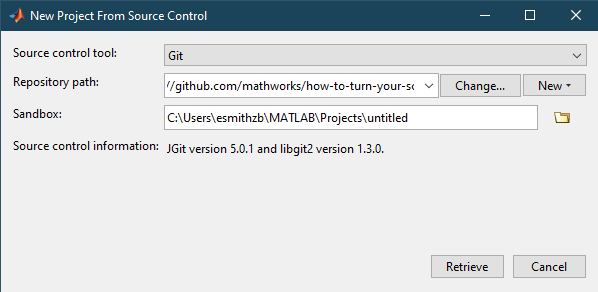

If you want, you can change the Sandbox location. You should change the folder name from untitled to something more descriptive, such as MATLAB-Live-Task-for-Python. If you are in MATLAB Online, you will need to select a MATLAB Drive location. Then select **Retrieve**. If the folder identified as the Sandbox does not exist, you will be prompted to create it.  

  **Pro-tip**. If you have a command-line Git installation, you can uncomment and run the following to download the Live Task.

% !git clone https://github.com/mathworks/MATLAB-Live-Task-for-Python.git

Change your current folder into the MATLAB-Live-Task-for-Python folder that you just cloned and then run the installation script 

install

which will open a pop-up window 

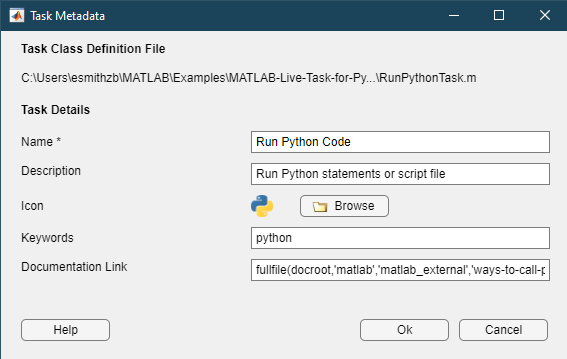

where you could access or change the name, description, icon, keywords, or documentation link for this Live Task. Select **Okay** to finish the installation. Then change directories back to Programming-A-Starter-Project-Using-MATLAB-with-Python.

  **Pro-tip**. If you downloaded the MATLAB-Live-Task-for-Python into the Programming-A-Starter-Project-Using-MATLAB-with-Python directory, you can programmatically change directories and install the new Live Task by uncommenting and running the code below. 

% cd MATLAB-Live-Task-for-Python
% install
% cd ..

## Try it out

### Run Python statements

  **Try**. Test your ability to use the Run Python Code Live Task.

- Clear your workspace, for ease of navigation, and set up variables to use as input.

clear
dollars = "$35.12";
percent = "5.9%";

        2. Insert the Live Task by going to the **Live Editor** tab, selecting the **Task** dropdown in the **Code **section of the toolstrip, and then selecting **Run Python Code**.

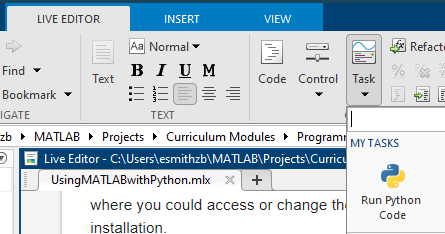

  **Pro-tip**. If you are using MATLAB Online, you may need to reload the page to refresh the dropdown menu.

Alternatively, you may simply type `python` in a code block, and the autocomplete feature will suggest the appropriate task:

% Running Python statements from Live Task
pythonCode5 = [
    "# Sample Python code"
    "amount = float(dollars.lstrip(""$""))"
    "rate = float(percent.rstrip(""%""))/100"
    "tax = amount*rate"
    "print(""The tax due is: "")"
    "print(round(tax,2))"
    ];
tax = pyrun(pythonCode5, "tax", "dollars", dollars, "percent", percent);

The tax due is: 
2.07


        3. Select the `+` to add Input and Output variables. You should have two input variables, `dollar` and `percent`, and one output variable, `tax`.

        4. Copy the sample Python code generated here into the Live Task and run it with different input values. 

If you want to use more elegant output formating, that is available depending on your Python version:

        5. Check that `tax` is a variable in the MATLAB Workspace. What value does it contain? 

tax

tax = 2.0721

You can select the "expand" arrow 

  on the bottom of the Live Task, or the breadcrumbs in the top right of the Live Task where you can select "Controls and Code", 

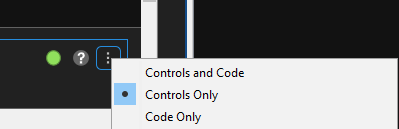

or even "Code Only" once you are satisfied with the code.  

### Run Python scripts

If you have a Python script, the Run Python Code Live Task also supports running scripts. To test this capability, there is a Python script in this folder called `helloworld.py` that takes one input variable called `name`. First, define a value for `name`:

name = "Team";

  **Try. Use the Run Python Code Live Task to run **`helloworld.py`**.**

        1. In the code box, below, insert the Run Python Code Live Task. 

        2. Select "Python script file" in the Run Python Code Live Task.

        3. Use your file selector to select the `helloworld.py` file in this folder.

        4. Add the input variable `name` from the Workspace with Python variable name `name`.

        5. Run this section. 

name = "Blake"

name = "Blake"

% Running Python script file from Live Task
pyrunfile("C:\Users\Tiana\Code\mine\Programming-A-Starter-Project-Using-MATLAB-and-Python\helloworld.py", "name", name);

Hello, Blake!


## Creating a Simple Weather Display

Now that you have installed and tested the Run Python Code Live Task, let's use it to help build a script that will check the current weather and short-term forecast and display the results. 

edit CheckingTheWeather.mlx

function localCheckPythonVersion
myPath = pwd;
if contains(myPath,"/MATLAB Drive/")
    localSetPythonEnvMO;
end
if isempty(pyenv().Version) || pyenv().Version == ""
    disp("Python is not installed.")
    web("https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html")
elseif pyenv().Version == "3.8" || pyenv().Version == "3.9"
    disp("You have an appropriate version of Python available.")
    disp("You are running Python " + pyenv().Version)
    if pyenv().Status == "Loaded"
        disp("Python was already on your MATLAB path.")
    else
        addpath(pyenv().Home)
        disp("Python has been added to your MATLAB path.")
    end
elseif pyenv().Version == "2.7"
    disp("You have Python 2.7 available.")
    disp("You can run Python code in this script, but you cannot complete the project unless you have Python 3.8 or 3.9")
    if pyenv().Status == "Loaded"

        disp("Python was already on your MATLAB path.")
    else
        addpath(pyenv().Home)
        disp("Python has been added to your MATLAB path.")
    end
else
    disp("You are running Python " + pyenv().Version)
    disp("That is not compatible with this script.")
    disp("Please follow the instructions in the documentation to proceed with this script.")
    web("https://www.mathworks.com/content/dam/mathworks/mathworks-dot-com/support/sysreq/files/python-compatibility.pdf")
    web("https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html")
end
end

function localSetPythonEnvMO
if pyenv().Status == "Loaded"
    if pyenv().Version == "2.7"
        disp("You have Python 2.7 loaded, but this module requires Python 3.8+.")
        disp("Please restart MATLAB Online by typing quit() at the command line,")
        disp("and then open MATLABwithPython.prj")
    else
        p = pyenv();
    end
elseif ~exist("p","var")
    p = pyenv("Version","/usr/bin/python3");   % for MATLAB Online
end
end

## Further Explorations

If this has whet your appetite, it is possible to go much farther with integrating code back and forth between [MATLAB and Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html). 

- Documentation on [calling Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html)

- Documentation on [calling MATLAB from Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)

- A deep learning example for [speech recognition](https://github.com/matlab-deep-learning/coexecution_speech_command)